Plot raw EEG waveforms for ASSR recordings.

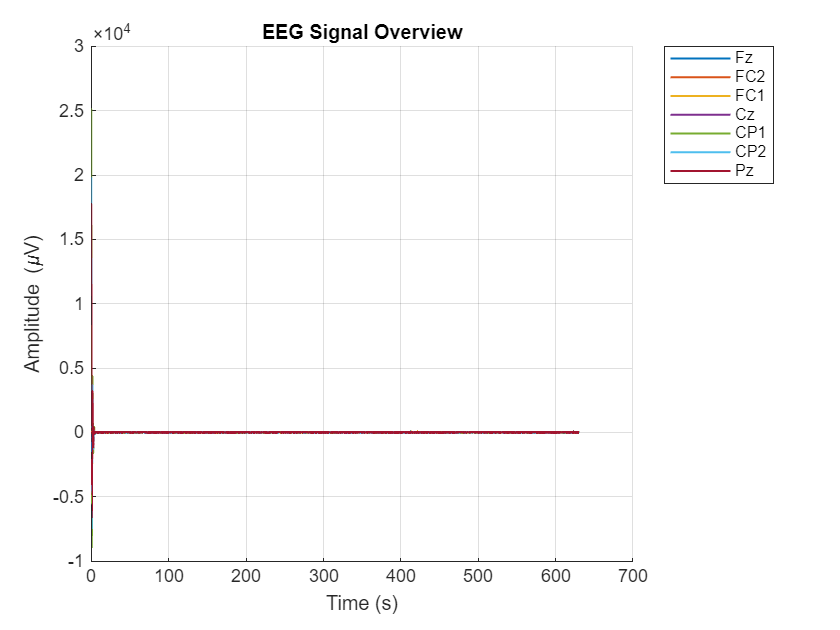

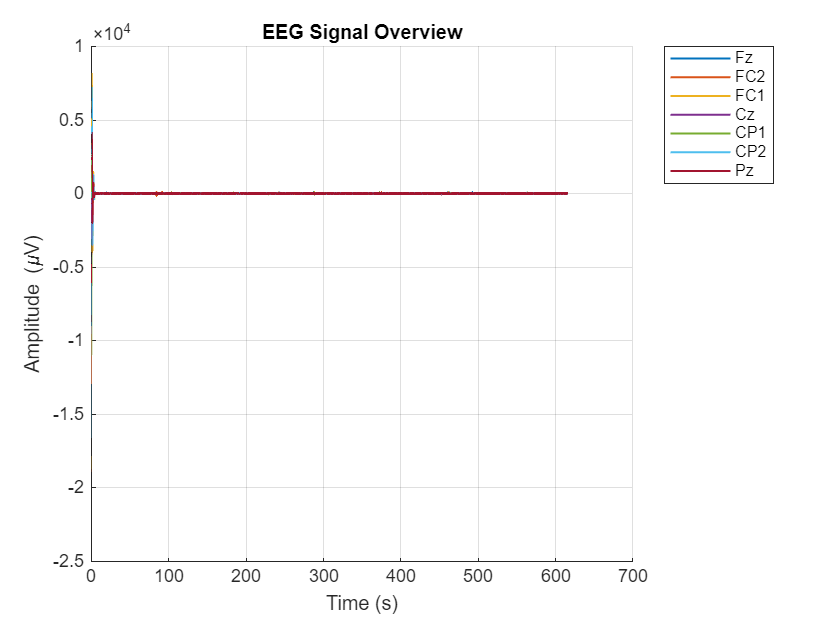

files = {'lab6_exp1_40hz_modulated_10min.mat', ...
         'lab6_trial4_30hz_modulated_10min_2.mat'};

chanNames = {'Fz','FC2','FC1','Cz','CP1','CP2','Pz'};

for f = 1:length(files)
    load(files{f});
    y = trigger.Data;        
    t = trigger.Time;      
    
    % Cols
    %  1: Fz
    %  2: FC2
    %  3: FC1
    %  4: Cz
    %  5: CP1
    %  6: CP2
    %  7: Pz
    %  8: Trigger (either 0 first/last 15s or 1 throughout modulated tone)
    chanIdx = 1:7;
    
    EEG = y(:,chanIdx)'; 
    trg = y(:,8)';       
    
    %get rid of DC offset
    for i = 1:size(EEG,1)
        EEG(i,:) = detrend(EEG(i,:), 'constant');
    end
    
    %plot
    figure('Color','w');
    hold on;
    for i = 1:length(chanIdx)
        plot(t, EEG(i,:), 'LineWidth', 1);
    end
    hold off; grid on;
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    title('EEG Signal Overview');
    legend(chanNames, 'Location', 'bestoutside');
end

The first ~10 seconds of each recording show some pretty visible startup artifacts, which is likely due to some amplifier settling or electrode adjustment. Since in later analyses remove these initial samples by retaining the data when the trigger is equal to 1, this should not affect any results or comparisons across trials.

**Plot the time waveform of all the sounds used in your experiments (only 100ms of the signal),**

**and their time-frequency decomposition (a.k.a. a spectrogram. Use MATLAB’s spectrogram()**

**function). (1 pts)**

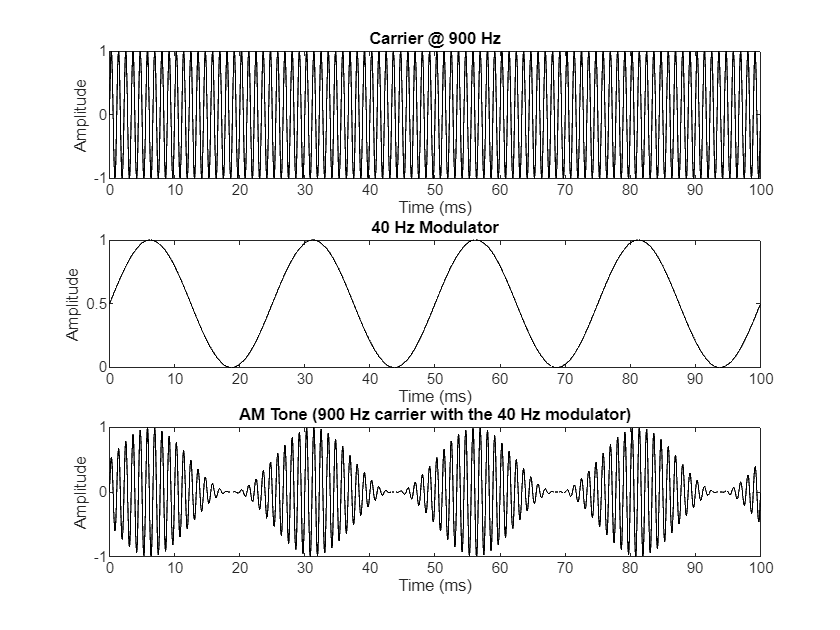

fs = 44100;       %audio
dur = 10;         % tone duration
t = (0:1/fs:dur)'; 

%carrier tone
fc = 900;
carrier = sin(2*pi*fc*t);

%40hz
fm40 = 40;
mod40 = 0.5*(1 + sin(2*pi*fm40*t));     %psoitive 
am40 = mod40 .* carrier;

%30hz
fm30 = 30;
mod30 = 0.5*(1 + sin(2*pi*fm30*t));
am30 = mod30 .* carrier;

%100ms
idx100ms = t <= 0.1;

figure('Color','w');
subplot(3,1,1);
plot(t(idx100ms)*1000, carrier(idx100ms), 'k');
xlabel('Time (ms)'); ylabel('Amplitude');
title('Carrier @ 900 Hz');

subplot(3,1,2);
plot(t(idx100ms)*1000, mod40(idx100ms), 'k');
xlabel('Time (ms)'); ylabel('Amplitude');
title('40 Hz Modulator');

subplot(3,1,3);
plot(t(idx100ms)*1000, am40(idx100ms), 'k');
xlabel('Time (ms)'); ylabel('Amplitude');
title('AM Tone (900 Hz carrier with the 40 Hz modulator)');

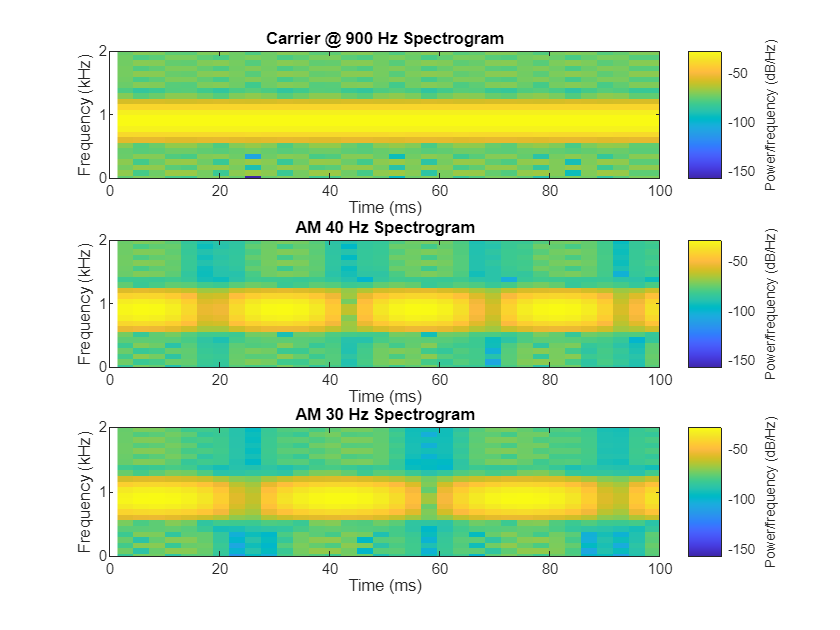


%spectrograms 
%%over same 100ms and plotting using 0-2kHz y axis 
figure('Color','w');

subplot(3,1,1);
spectrogram(carrier,256,128,512,fs,'yaxis');
ylim([0 2]);                     % could adjust 
xlim([0 0.1]);                   %100ms
xticks(0:0.02:0.1);
xticklabels(0:20:100);
xlabel('Time (ms)');
ylabel('Frequency (kHz)');
title('Carrier @ 900 Hz Spectrogram');

subplot(3,1,2);
spectrogram(am40,256,128,512,fs,'yaxis');
ylim([0 2]);
xlim([0 0.1]);
xticks(0:0.02:0.1);
xticklabels(0:20:100);
xlabel('Time (ms)');
ylabel('Frequency (kHz)');
title('AM 40 Hz Spectrogram');

subplot(3,1,3);
spectrogram(am30,256,128,512,fs,'yaxis');
ylim([0 2]);
xlim([0 0.1]);
xticks(0:0.02:0.1);
xticklabels(0:20:100);
xlabel('Time (ms)');
ylabel('Frequency (kHz)');
title('AM 30 Hz Spectrogram');

**Load the EEG signal in MATLAB and use the trigger you generated in your s-function to**

**separate the EEG response only when the sound was playing. Since the tone you played was**

**modulated at a particular frequency, the best way to analyze it is in the frequency domain.**

**Take the Fourier transform of each channel, and start your analysis by averaging the magnitude**

**of the FFT over all channels.**

**Plot the average magnitude. You can expect to see a peak at 40Hz in the EEG data. (1 pt)**

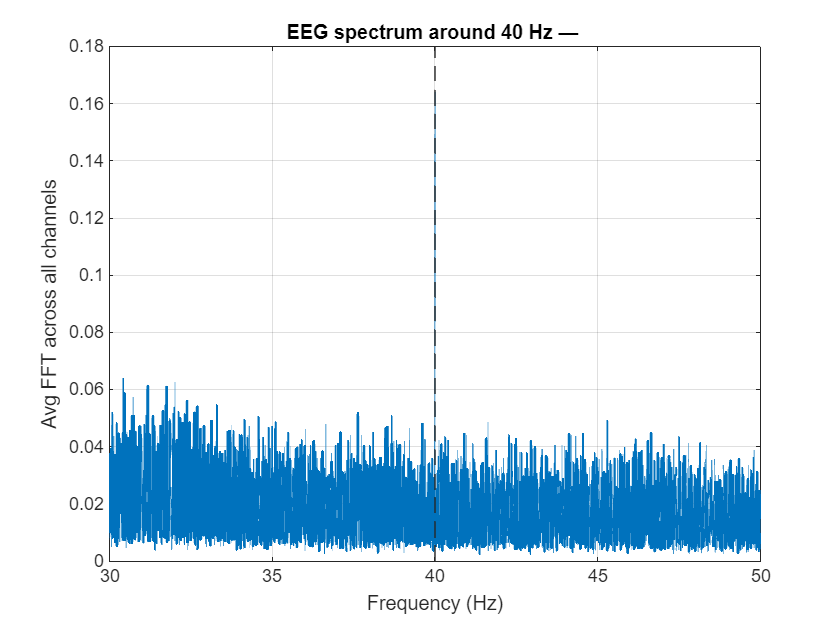

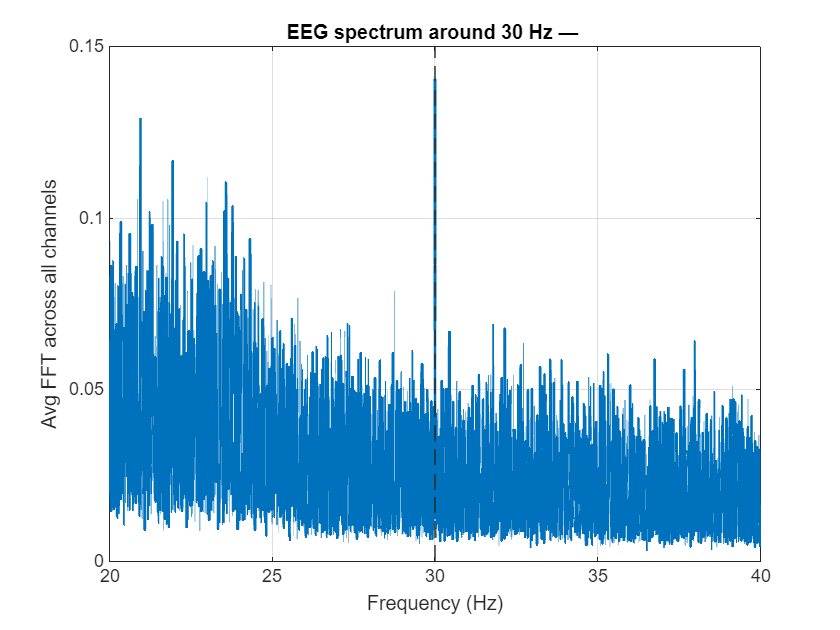


fs = 352;    %the sampling rate used in our experiment (this was the bug that messed everything up)
files = {'lab6_exp1_40hz_modulated_10min.mat', ...
         'lab6_trial4_30hz_modulated_10min_2.mat'};

for f = 1:numel(files)
    load(files{f});                  % 
    Y = trigger.Data;                %N x 8
    t = trigger.Time;              
    EEG = Y(:,1:7)';                
    trg = Y(:,8)';                 

    %only want when equal to 1
    keep = (trg == 1);
    if ~any(keep)
        warning('No trigger==1 samples in %s', files{f});
        continue
    end
    X = EEG(:, keep);                % now we have 7 x M

    %remove DC per channel
    for k = 1:size(X,1)
        X(k,:) = detrend(X(k,:), 'constant');
    end

    % Okay FFT per channel, the one-sided magnitude, then we take the average
    M = size(X,2);
    N = 2^nextpow2(M);
    FX = zeros(size(X,1), N/2+1);

    for k = 1:size(X,1)
        Xk = X(k,:);
        Xk = [Xk, zeros(1, N - M)];          
        Fk = fft(Xk, N) / M;
        F1 = Fk(1:N/2+1);
        F1(2:end-1) = 2*F1(2:end-1);        
        FX(k,:) = abs(F1);
    end

    fHz = (0:N/2) * fs / N;
    avgMag = mean(FX, 1);

    %a little thing to determine the expected modulation frequency from the
    %file name, keep resusing 
    if contains(lower(files{f}), '40hz')
        modFreq = 40;
    elseif contains(lower(files{f}), '30hz')
        modFreq = 30;
    else
        modFreq = 40;  % Just the default
    end

    % plot zoomed view ±10 Hz around modulation frequency for a better
    % visual
    figure('Color','w');
    plot(fHz, avgMag, 'LineWidth', 1.5);
    grid on;
    xlim([modFreq-10 modFreq+10]);
    xlabel('Frequency (Hz)');
    ylabel('Avg FFT across all channels');
    title(sprintf('EEG spectrum around %d Hz — %s', modFreq));
    xline(modFreq, '--', 'LineWidth', 1);
end

**If the length of the FFT is L, given the sampling frequency of your EEG signal (256Hz), what**

**sample in FFT corresponds to the modulator frequencies you used (40Hz, 30 Hz)? (1 pt)**

bin30 = round(30 * N / fs) + 1;
bin40 = round(40 * N / fs) + 1;

fprintf('FFT bin for 30 Hz = %d\n', bin30);

FFT bin for 30 Hz = 22343


fprintf('FFT bin for 40 Hz = %d\n', bin40);

FFT bin for 40 Hz = 29790



% lets show the freq. resolution
df = fs / N;
fprintf('Each FFT bin represents %.4f Hz\n', df);

Each FFT bin represents 0.0013 Hz


%sanity checks 
df = fs / N;                 
f_from_30 = (bin30-1)*df;    %should be 30
f_from_40 = (bin40-1)*df;    %should be 40
[f_from_30, f_from_40]

ans =    30.0002   39.9999


**Use the following command to plot the one-sided spectrum: plot(linspace(0, FS/2,N),f(1:end/2)),**

**and mark the modulator frequencies on the plots for each condition. Measure the normalized**

**ASSR component by dividing the magnitude of the Fourier transform by its sum. Each Fourier**

**coefficient now represents the relative power at that frequency, instead of overall power. (1 pts)**

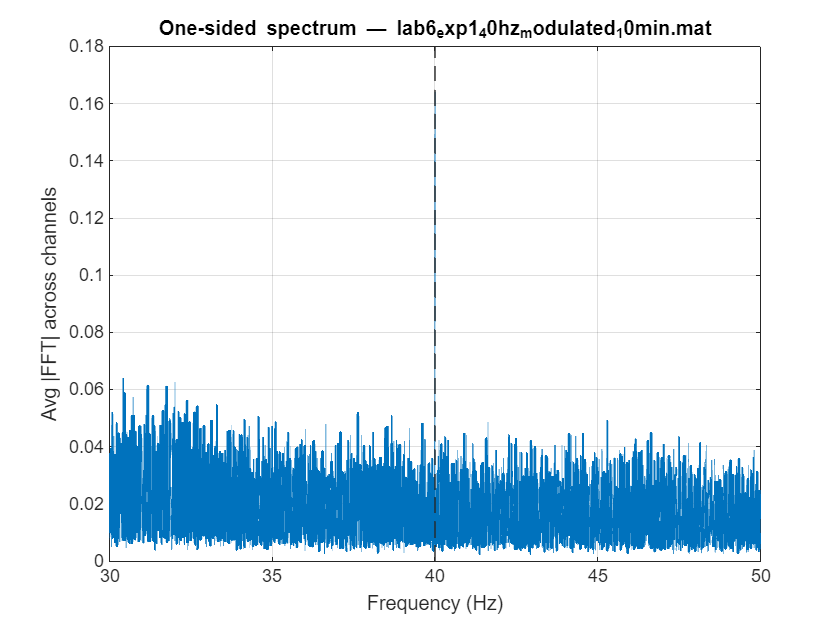

lab6_exp1_40hz_modulated_10min.mat: normalized ASSR at 40 Hz = 0.000072 (unitless)


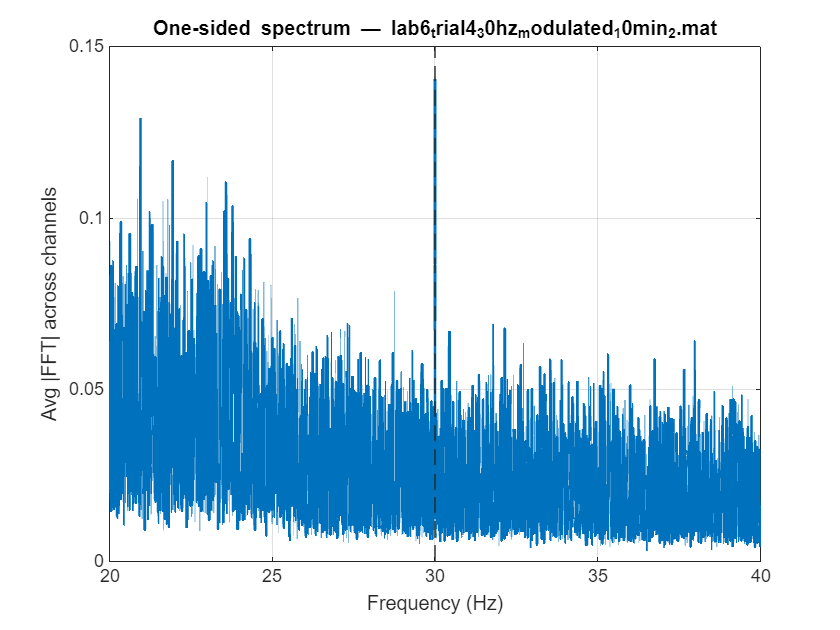

lab6_trial4_30hz_modulated_10min_2.mat: normalized ASSR at 30 Hz = 0.000051 (unitless)


fs = 352;
files = {'lab6_exp1_40hz_modulated_10min.mat', ...
         'lab6_trial4_30hz_modulated_10min_2.mat'};

for f = 1:numel(files)
    load(files{f});                  
    Y = trigger.Data;               
    EEG = Y(:,1:7)';                 
    trg = Y(:,8)';                  

    keep = (trg == 1);
    if ~any(keep)
        warning('No trigger==1 samples in %s', files{f});
        continue
    end
    X = EEG(:, keep);                % [7 x M]

    for k = 1:size(X,1)
        X(k,:) = detrend(X(k,:), 'constant');
    end

    % #mostly the same stuff
    M = size(X,2);
    N = 2^nextpow2(M);
    FX = zeros(size(X,1), N/2+1);
    for k = 1:size(X,1)
        Xk = [X(k,:), zeros(1, N - M)];
        Fk = fft(Xk, N) / M;
        F1 = Fk(1:N/2+1);
        F1(2:end-1) = 2*F1(2:end-1);
        FX(k,:) = abs(F1);
    end
    fHz = linspace(0, fs/2, N/2+1);     % the one-sided frequency axis
    avgMag = mean(FX, 1);               %then averaged across channels

    if contains(lower(files{f}), '40hz'), modFreq = 40;
    elseif contains(lower(files{f}), '30hz'), modFreq = 30;
    else, modFreq = 40; end

    %plot(linspace(0,FS/2,N), f(1:end/2))
    figure('Color','w');
    plot(fHz, avgMag, 'LineWidth', 1.5); grid on;
    xlim([modFreq-10, modFreq+10]);
    xlabel('Frequency (Hz)');
    ylabel('Avg |FFT| across channels');
    title(sprintf('One-sided spectrum — %s', files{f}));
    xline(modFreq,'--','LineWidth',1);

    % normalized spectrum and then the normalized ASSR component
    normSpec = avgMag / sum(avgMag);        % where the each coeff is equal to the relative power
    [~, idx] = min(abs(fHz - modFreq));     % finding the nearest bin to modFreq
    normASSR = normSpec(idx);

    fprintf('%s: normalized ASSR at %d Hz = %.6f (unitless)\n', ...
            files{f}, modFreq, normASSR);
end

**Next, we will determine how much data is needed to get a good ASSR measurement. To answer**

**this important question, repeat your analysis for cumulative 30s intervals (i.e. first 30s, first 60s,**

**first 90s, ...). Display the relative magnitude of the ASSR as a function of signal duration.**

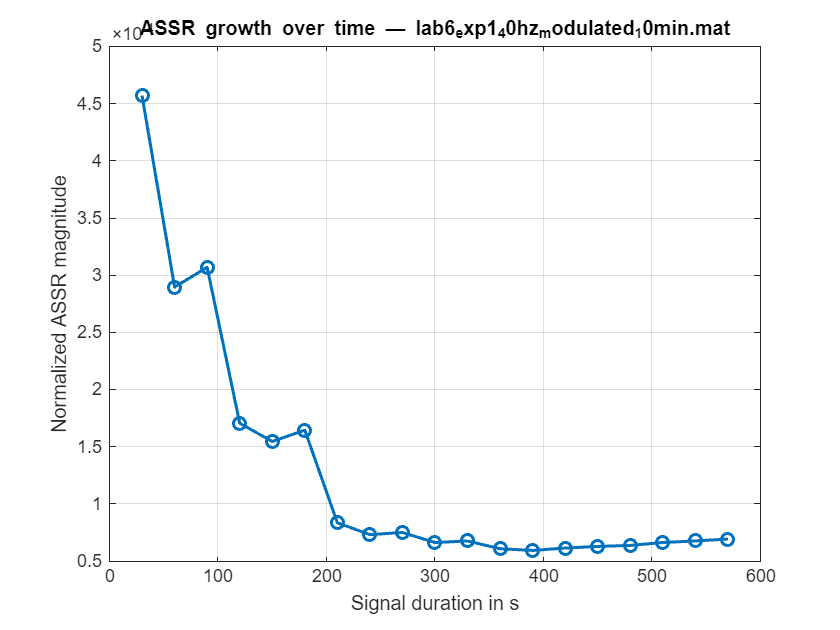

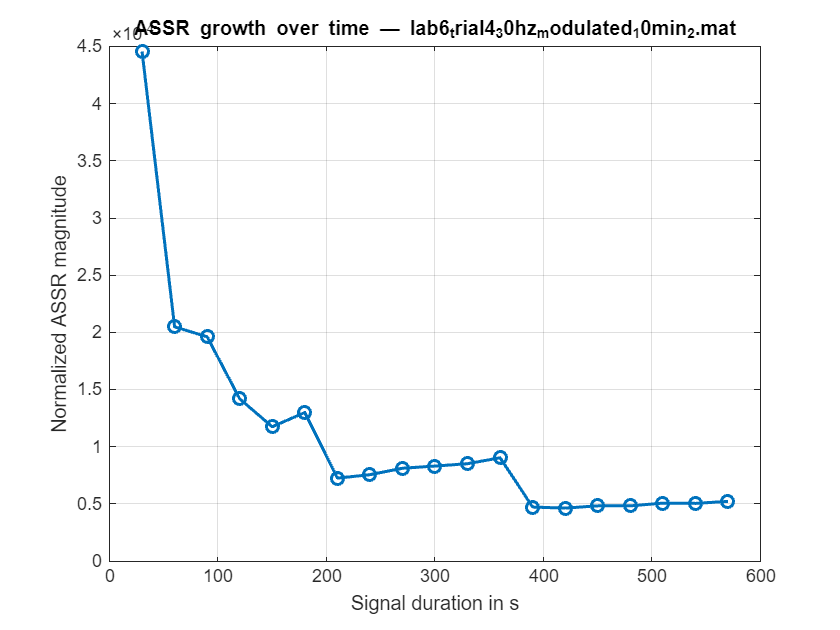

fs = 352;
interval = 30;   % seconds per our step
files = {'lab6_exp1_40hz_modulated_10min.mat', ...
         'lab6_trial4_30hz_modulated_10min_2.mat'};

for f = 1:numel(files)
    load(files{f});                 
    Y = trigger.Data;             
    EEG = Y(:,1:7)';          
    trg = Y(:,8)';

    keep = (trg == 1);
    if ~any(keep)
        warning('No trigger==1 samples in %s', files{f});
        continue
    end
    X = EEG(:, keep);   
    t = trigger.Time(keep);

    if contains(lower(files{f}), '40hz'), modFreq = 40;
    elseif contains(lower(files{f}), '30hz'), modFreq = 30;
    else, modFreq = 40; end

    % the total available time to use 
    total_dur = t(end) - t(1);
    step_samples = interval * fs;
    num_steps = floor(total_dur / interval);

    normASSR_vals = zeros(1,num_steps);
    durations = (1:num_steps) * interval;

    for s = 1:num_steps
        % and then the first s steps 
        sample_count = min(size(X,2), round(durations(s) * fs));
        segment = X(:, 1:sample_count);

        % detrend and FFT too
        for k = 1:size(segment,1)
            segment(k,:) = detrend(segment(k,:), 'constant');
        end
        M = size(segment,2);
        N = 2^nextpow2(M);
        FX = zeros(size(segment,1), N/2+1);
        for k = 1:size(segment,1)
            Fk = fft(segment(k,:), N)/M;
            F1 = Fk(1:N/2+1);
            F1(2:end-1) = 2*F1(2:end-1);
            FX(k,:) = abs(F1);
        end
        fHz = linspace(0, fs/2, N/2+1);
        avgMag = mean(FX,1);

        % normalize and then lets extract the ASSR bin
        normSpec = avgMag / sum(avgMag);
        [~, idx] = min(abs(fHz - modFreq));
        normASSR_vals(s) = normSpec(idx);
    end

    % Then plot the normalized ASSR magnitude v the cumulative. duration
    figure('Color','w');
    plot(durations, normASSR_vals, 'o-', 'LineWidth', 1.5);
    grid on;
    xlabel('Signal duration in s');
    ylabel('Normalized ASSR magnitude');
    title(sprintf('ASSR growth over time — %s', files{f}));
end

**At what duration can you reliably detect the presence of the ASSR? Does the signal get stronger**

**the more data you include, or does it reach a plateau after a certain duration? Do you think you**

**collected enough data? If not, how much more do you think you need to reach a plateau? (5 pts)**

For the 40 Hz modulation condition, It appears that the normalized ASSR magnitude decreases sharply at first and then happens to stabilize around the 200 second mark. Beyond that point, it seems that the curve remains nearly flat, indicating that around three to four minutes of EEG are sufficient to obtain a reliable 40 Hz steady-state response for these particular conditions. 

However, for the 30 Hz condition, we can observe that this trend is more gradual. The response first reaches a temporary plateau between roughly 200 s and 350 s, which is then followed by a lower and more final plateau beginning near our 400s mark. I believe that this two-stage flattening could suggest that the 30 Hz response may require a slightly longer recording perhaps around six to seven minutes (at least as far as our group was recording) before the estimate of the ASSR manages to stabilize.

Overall, I would say that the data tends to show that the ASSR becomes progressively more stable as additional EEG data are averaged. With that said, it seems as if this improvement slows once enough of the cycles of the amplitude-modulated tone have been captured. So, in this lab, which seeks to examine how the auditory steady-state responses manages to emerge from a continuous 30 Hz and 40 Hz amplitude-modulated tones, about 3 minutes of data are enough for 40 Hz and 6–7 minutes for 30 Hz to reach a plateau. Since each of our trials contained roughly 10 minutes of recording, I would say that the amount of data collected was more than enough to achieve a robust and reliable measurement of the ASSR at both of our modulation frequencies.

**Measure the ASSR component separately for all channels at the modulator frequency (40Hz in condition 1, 30Hz in condition 2). Use the scalp map to show the relative magnitude of the ASSRs at all electrodes under each experimental condition (30Hz and 40Hz). Which electrodes recorded the largest ASSR component? (1 pt)**

%it is important that you run addpath('C:\Users\Alexander
%Speer\Desktop\Columbia Fall 2025\BCI Lab\Lab 6\eeglab14_1_2b') in the CLI before you
%run this code cell. 

%another thing: make sure that you type 'eeglab' in the CLI as well before
%running this cell. You need both.
fs = 352;
files = {'lab6_exp1_40hz_modulated_10min.mat', ...
         'lab6_trial4_30hz_modulated_10min_2.mat'};
chanNames = {'Fz','FC2','FC1','Cz','CP1','CP2','Pz'};
locs_path = 'BCI.locs';
selLocIdx = [1 2 3 6 7 8 11];

chanlocs = readlocs(locs_path);

readlocs(): 'loc' format assumed from file extension


lab6_exp1_40hz_modulated_10min.mat: 40 Hz ASSR strongest = Fz (SNR 1.01 dB)


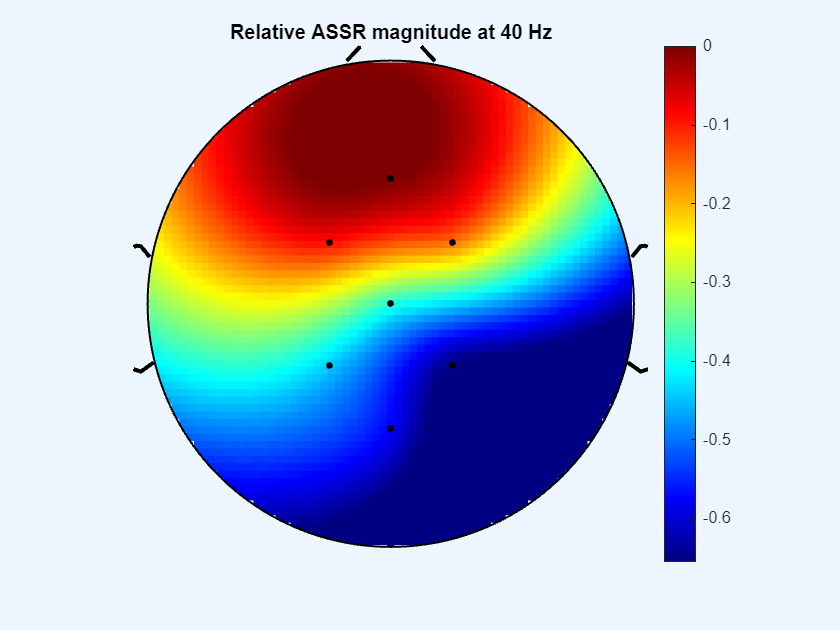

lab6_trial4_30hz_modulated_10min_2.mat: 30 Hz ASSR strongest = FC1 (SNR -0.05 dB)


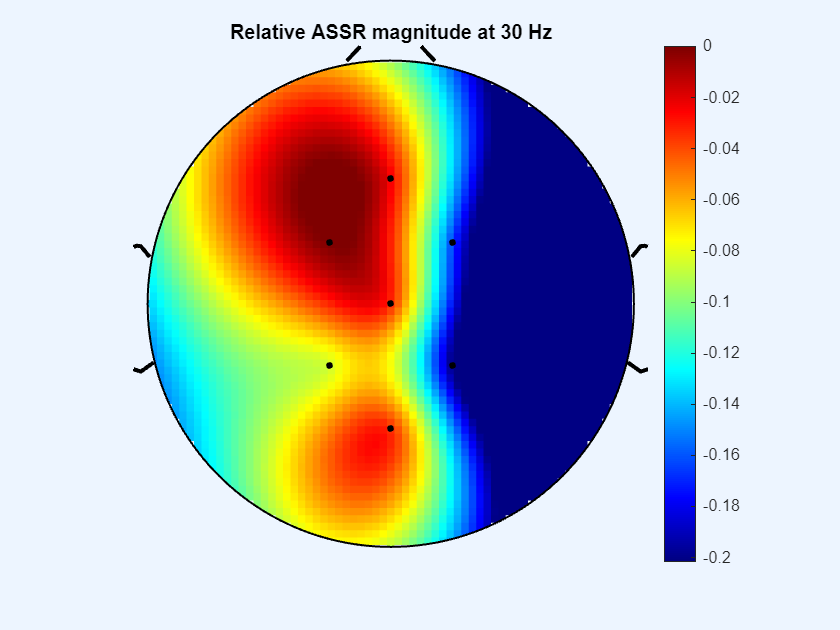

chanlocs = chanlocs(selLocIdx);

nfft = 2^nextpow2(10*fs);
win  = round(4*fs);
olap = round(0.5*win);

for f = 1:numel(files)
    S = load(files{f});  y = S.trigger.Data;
    trg = y(:,8) > 0.5;
    X   = y(trg,1:7)';                 %7 x M
    X   = X - mean(X,2);

    % get the welch per channel
    P = zeros(7, nfft/2+1);
    for ch = 1:7
        [pxx, fHz] = pwelch(X(ch,:), hamming(win), olap, nfft, fs, 'onesided');
        P(ch,:) = pxx(:).';
    end

    modFreq = contains(lower(files{f}),'40')*40; if modFreq==0, modFreq=30; end

    %Finding the narrow-band SNR at whatever modFreq were on
    bw_sig  = 0.5;                      % lets ±0.5 Hz the signal band
    bw_nb   = [1 3];                    % and then noise sidebands 1–3 Hz away
    sig_ix  = (fHz>=modFreq-bw_sig) & (fHz<=modFreq+bw_sig);
    nb_ix   = ((fHz>=modFreq-bw_nb(2)) & (fHz<=modFreq-bw_nb(1))) | ...
              ((fHz>=modFreq+bw_nb(1)) & (fHz<=modFreq+bw_nb(2)));

    sigP = mean(P(:,sig_ix),2);
    nbP  = mean(P(:,nb_ix),2);
    snr_db = 10*log10(sigP./nbP);       % 7×1

    % have to norm.to the max within this condition for us to actually get a clear map
    vals = snr_db - max(snr_db);        % we can see that 0 dB is going to be the strongest channel

    %get our winners 
    [mx, imx] = max(snr_db);
    fprintf('%s: %d Hz ASSR strongest = %s (SNR %.2f dB)\n', ...
            files{f}, modFreq, chanNames{imx}, mx);

    % IMPORTANT TOPOPLOT
    figure('Color','w','Name',sprintf('ASSR %d Hz SNR (dB rel. max)',modFreq));
    topoplot(vals, chanlocs, 'electrodes','on', 'numcontour', 6, 'style','map', 'plotrad',0.5);
    caxis([min(vals) 0]); colorbar; title(sprintf('Relative ASSR magnitude at %d Hz', modFreq));
end

At 40 Hz, we can see that the largest ASSR component was recorded at Fz with a SNR ≈ 1.0 dB.

At our 30 Hz condition, the largest ASSR component was recorded at FC1 with SNR ≈ −0.05 dB.

I believe that the scalp maps show strongest responses over the fronto-central region, which from what I have seen appears to be consitant with auditory steady-state responses generated by cthe ortical auditory areas.